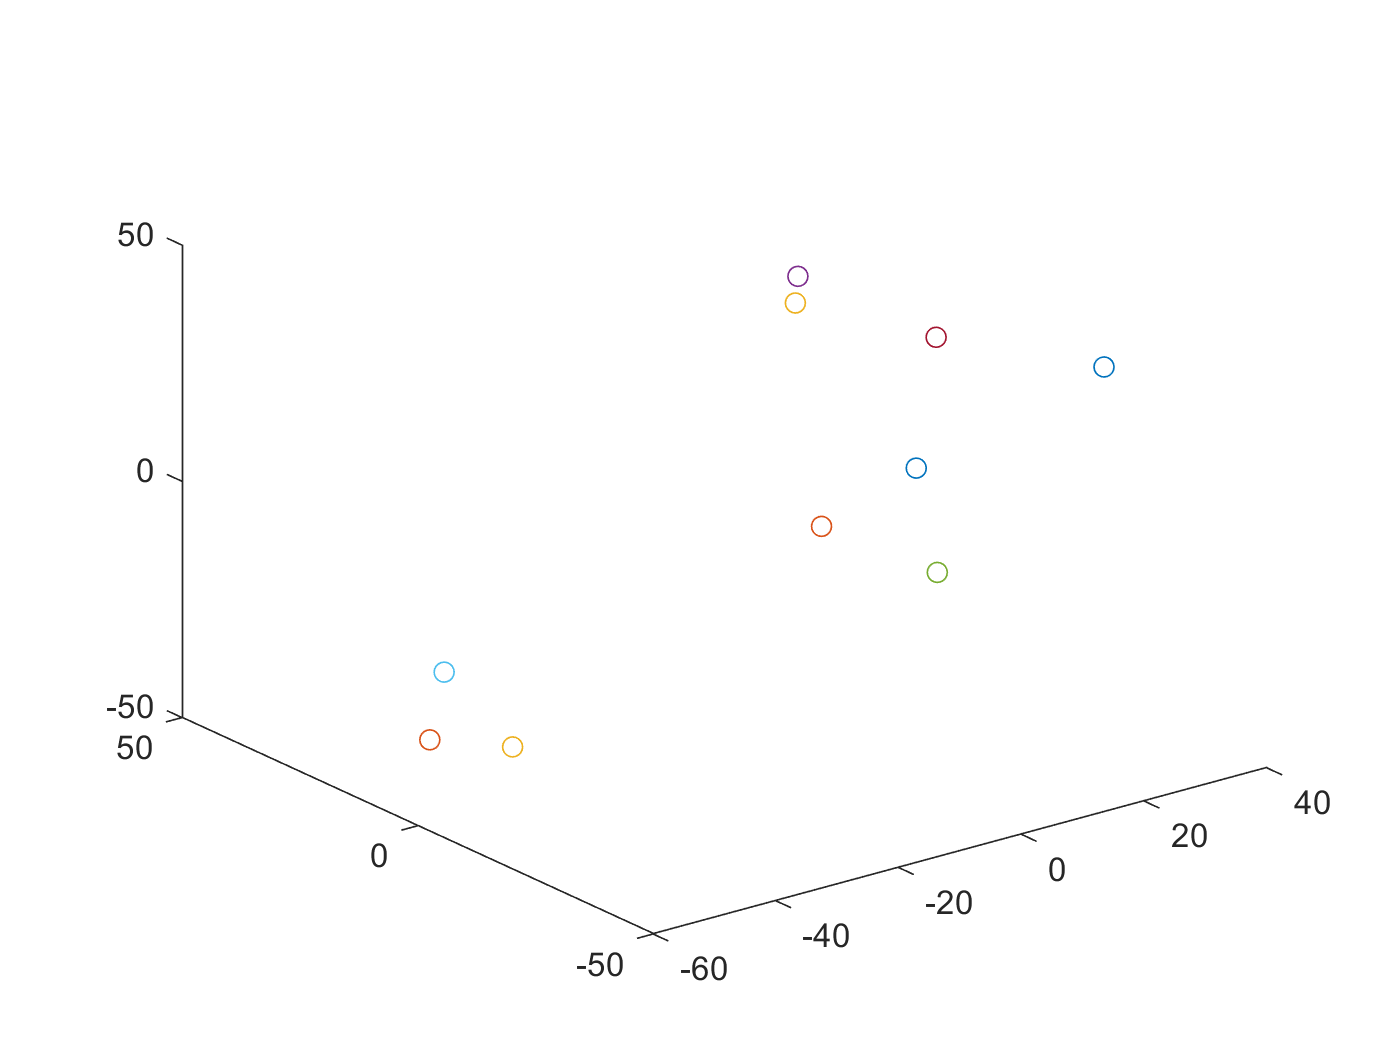

%create a set of 10 random 3D points
points = zeros(3 ,10);
figure();
for  j = 1:10
    for i = 1:3
        points(i,j) = 100*rand - 50; %generate a random coordinate between -50 and 5
    end
    
    plot3(points(1,j) , points(2,j) , points(3,j) , 'Marker' , 'o');
    hold on;
end


points_3D= [points; ones(1,10)] %needed to transform everything in homogeneous coordinates

points_3D =    39.0923  -30.2190    0.0022   10.9867   30.5489  -26.0068   -1.0099   21.2694  -44.0381  -42.8555
  -16.5837  -46.9459   -2.0078   11.7666    7.6722   38.6512  -33.2073    0.0472   18.1972    2.1650
   19.8746   24.4074   40.4722   35.9442  -31.7078  -47.1326   47.8681   -2.8912  -45.7569  -40.3270
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



f = 1; %for the moment assume focal lenght unitary;
%initialization of the pose of the camera
R = eye(3); 
T = [0;0;0];

%pose = rigid3d(R,T);

'rigid3d' requires Image Processing Toolbox.

%cam = plotCamera('AbsolutePose',pose,'Size',20);

%GREAT ASSUMPTION OF CALIBRATED CAMERA
%Define the intrinsic parameter matrices

K_f = [f 0 0; 0 f 0; 0 0 1];
K_s = eye(3); %for the moment assume no distortion on the pixel's squareness
PI_0 = [eye(3) , [0;0;0]];



%Define the EXTRINSIC parameter matrix to be updated every cycle
g = [R , T;
    0 0 0 1] 

g =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1





%UPDATE THE INFO ON POSE 6DOF
%R

%Set a Z value constant to for example 1, so lambda = 1
lambda = 1

lambda = 1

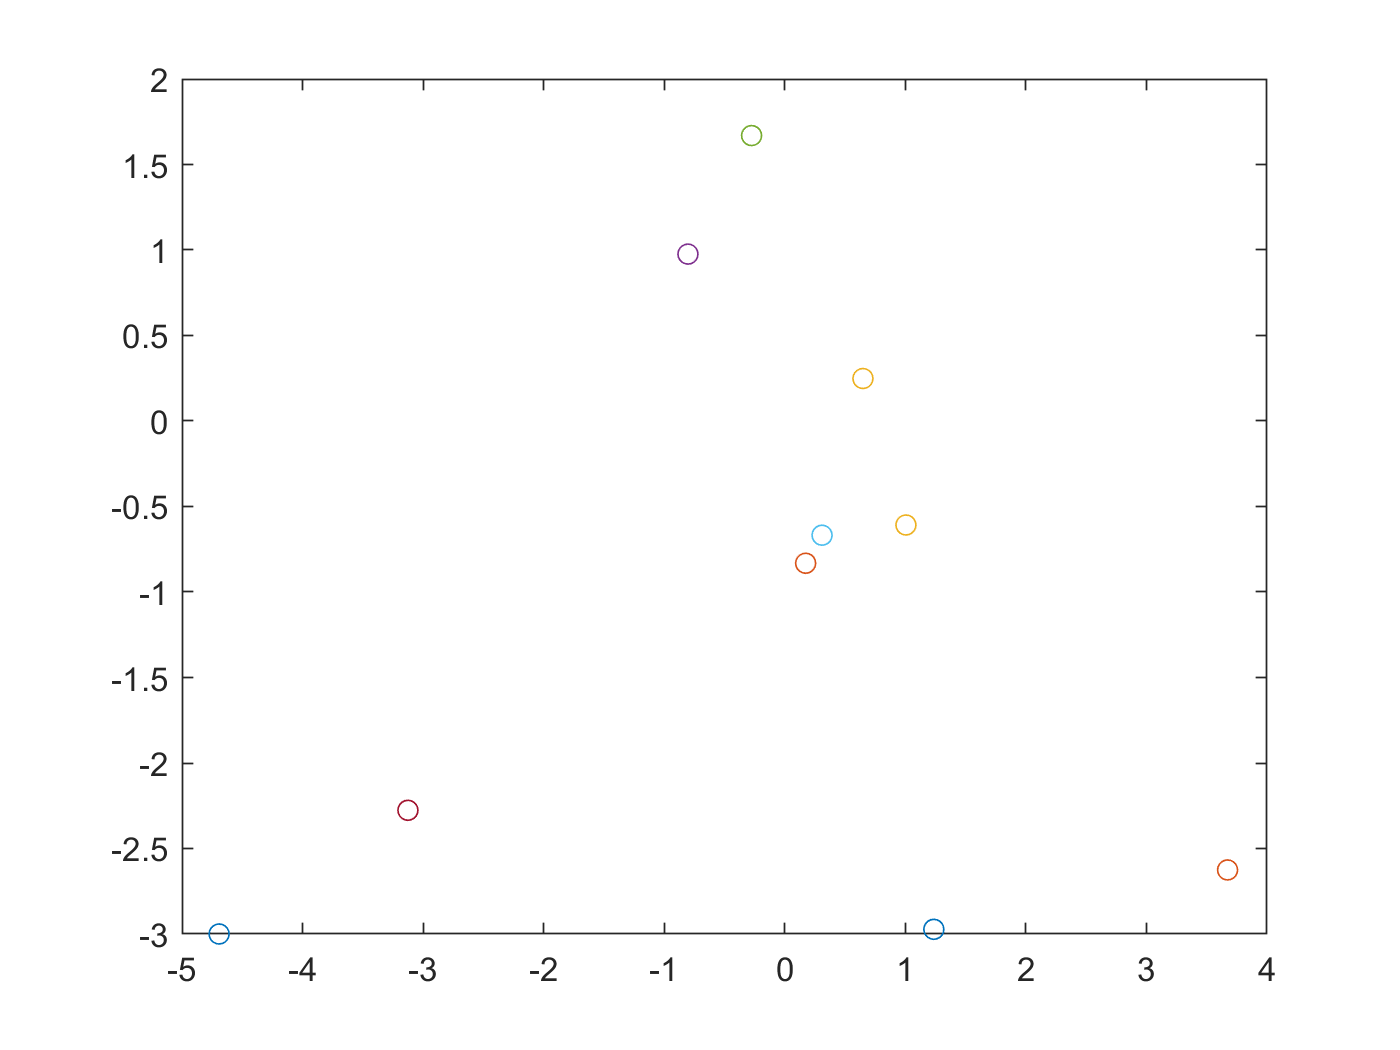

q = K_s*K_f*PI_0*g * points_3D; %project the 3D points into the image plane
q = q + (rand([3 , 10]) - 0.5); %add some quantization noise to the projected points

%perform the normalization of the points in order to have scaling factor =
%1
figure();
for j = 1:10
    q(:,j) = q(:,j) / q(3,j); %normalize points
    plot(q(1,j) , q(2,j), 'Marker','o');
    hold on;
end